# Exergy Analysis Demo

Use `ExergyAnalysys` function to obtain the exergy balances and Table FP for one state of the plant

#### Read the Data Model

file="D:\Documents\Proyectos\TaesLab\Examples\rorc\rorc_model.json";
data=ReadDataModel(file);

#### Select the state of the plant to analyze

states=convertCharsToStrings(data.States);
state=convertStringsToChars(states(1));

#### Get Exergy Analysis

Use function `ExergyAnalysis `to get the exergy balance por the selected state, and print de processes balance using function `ShowResults`

res=ExergyAnalysis(data,'State',state);
ShowResults(res,'Table','eprocesses');

Processes Exergy Table

Key         F(kW)       P(kW)       I(kW)      k(J/J)      η (%)
—————————————————————————————————————————————————————————————————
BLR       100.000      74.150      25.850      1.3486      74.15
TRB        65.670      52.447      13.223      1.2521      79.86
IHE         2.110       1.543       0.567      1.3675      73.13
PMP         2.447       2.093       0.354      1.1691      85.53
CND        10.006      10.006       0.000      1.0000     100.00
ENV       100.000      50.000      50.000      2.0000      50.00



#### Show the Diagram FP

Show the Diagram FP as graph using `ShowGraph` function, and as Matlab table using Export`Table` function

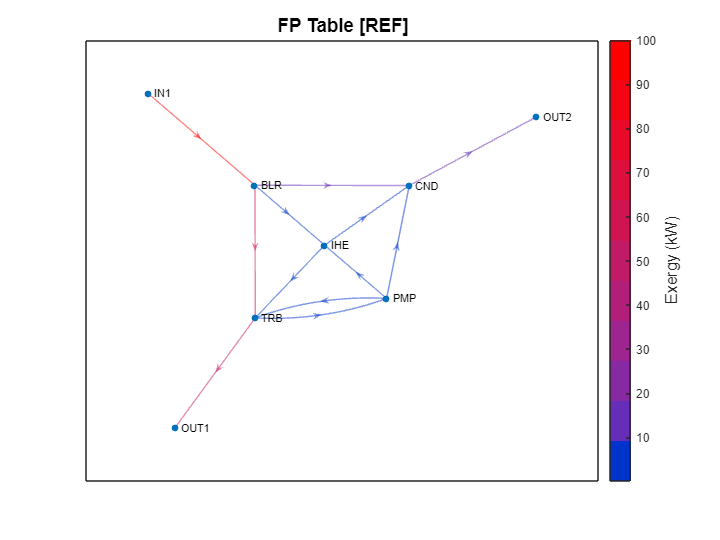

ShowGraph(res)

tbl=ExportResults(res,'Table','tfp','ExportAs','TABLE')

tbl = 7×7 table
             BLR     TRB        IHE        PMP       CND       ENV      Total 
             ___    ______    ________    _____    _______    ______    ______
    BLR        0      62.6      2.0114        0     9.5383         0     74.15
    TRB        0         0           0    2.447          0        50    52.447
    IHE        0    1.3027    0.041855        0    0.19848         0     1.543
    PMP        0     1.767    0.056774        0    0.26923         0     2.093
    CND        0         0           0        0          0    10.006    10.006
    ENV      100         0           0        0          0         0       100
    